m_exc=[];
match=table();
s=1;
while s<height(data)
    m_ex=[];
    for k=s:height(data)
        if k==height(data)
            j=k;
            break;
        end
        if data{k+1,"match"}-data{k,"match"}~=0||data{k+1,"round"}-data{k,"round"}~=0
            j=k;
            
            break;
        end
    end
    match=data(s:j,:);
    %局数差
    g_diffe=[];
    round_no=[];
    match_no=[];
    n=1;
    for i=1:height(match)
        if i==height(match)
            break;
        end
        if match{i+1,"set_no"}-match{i,"set_no"}~=0 %当set数发生变化时
            n=1;
        end
        if match{i,"game_no"}==n %因为一个game内局数差不变，所以每个game只用取一次
            g_diffe(end+1)=match{i,"p1_games"}-match{i,"p2_games"};
            round_no(end+1)=match{i,"round"};
            match_no(end+1)=match{i,"match"};
            n=n+1;
        end
    end
    round_no=round_no';%转置，不用管
    match_no=match_no';
    g_differ=g_diffe';
    m_ex=[m_ex,round_no];%加入表
    m_ex=[m_ex,match_no];
    m_ex=[m_ex,g_differ];

    %获胜时小分差
    p_diffe=[];
    for i=1:height(match)
        if i==height(match)%防止溢出
            p_diffe(end+1)=score2point(match{i,"p1_score"})-score2point(match{i,"p2_score"});
            break;
        end
        if match{i+1,"game_no"}-match{i,"game_no"}~=0%game数发生变化及进入下一局时，记录当时的点数差
            p_diffe(end+1)=score2point(match{i,"p1_score"})-score2point(match{i,"p2_score"});
        end
    end
    p_differ=p_diffe';
    m_ex=[m_ex,p_differ];

    %绝杀球与失误次数
    p1_ac=[];
    p2_ac=[];
    p1_faul=[];
    p2_faul=[];
    pa1=0;
    pa2=0;
    pf1=0;
    pf2=0;
    for i=1:height(match)
        pa1=pa1+match{i,"p1_ace"};%求和
        pa2=pa2+match{i,"p2_ace"};
        pf1=pf1+match{i,"p1_double_fault"}+match{i,"p1_unf_err"};
        pf2=pf2+match{i,"p2_double_fault"}+match{i,"p2_unf_err"};
        if i==height(match)
            p1_ac(end+1)=pa1;%防溢出
            p2_ac(end+1)=pa2;
            p1_faul(end+1)=pf1;
            p2_faul(end+1)=pf2;
            break;
        end
        if match{i+1,"game_no"}-match{i,"game_no"} ~=0%game发生变化时，输出求和结果
            p1_ac(end+1)=pa1;
            p2_ac(end+1)=pa2;
            p1_faul(end+1)=pf1;
            p2_faul(end+1)=pf2;
            pa1=0;
            pa2=0;
            pf1=0;
            pf2=0;
        end
    end

    p1_ace=p1_ac';
    p2_ace=p2_ac';
    p1_fault=p1_faul';
    p2_fault=p2_faul';

    m_ex=[m_ex,p1_ace];
    m_ex=[m_ex,p2_ace];
    m_ex=[m_ex,p1_fault];
    m_ex=[m_ex,p2_fault];

    %跑动距离
    p1_di=[];
    p2_di=[];
    pd1=0;
    pd2=0;
    n=0;
    for i=1:height(match)
        pd1=pd1+match{i,"p1_distance_run"};
        pd2=pd2+match{i,"p2_distance_run"};
        n=n+1;
        if i==height(match)
            p1_di(end+1)=pd1/n;
            p2_di(end+1)=pd2/n;
            break;
        end
        if match{i+1,"game_no"}-match{i,"game_no"} ~=0
            p1_di(end+1)=pd1/n;
            p2_di(end+1)=pd2/n;
            pd1=0;
            pd2=0;
            n=0;
        end
    end

    p1_dis=p1_di';
    p2_dis=p2_di';
    m_ex=[m_ex,p1_dis];
    m_ex=[m_ex,p2_dis];

    %是否发球
    serve=[];
    n=1;
    for i=1:height(match)
        if i==height(match)
            break;
        end
        if match{i+1,"set_no"}-match{i,"set_no"}~=0
            n=1;
        end
        if match{i,"game_no"}==n
            serve(end+1)=match{i,"server"};
            n=n+1;
        end
    end

    server=serve';
    m_ex=[m_ex,server];
    m_exc=cat(1,m_exc,m_ex);
    s=k+1;
end

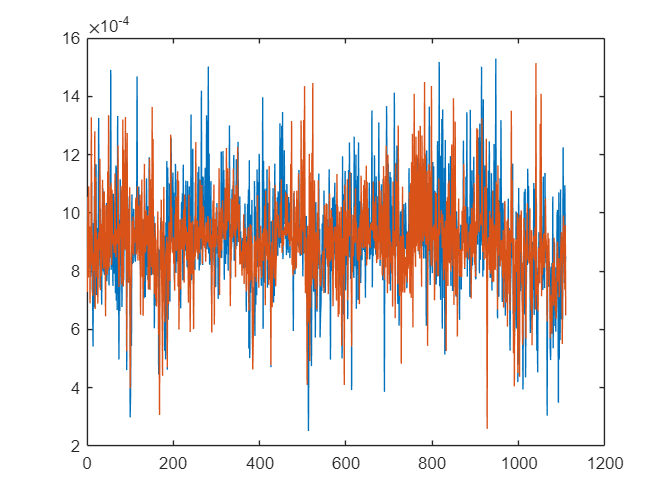

res1=AHPTOPSIS3(m_exc,1);
res2=AHPTOPSIS3(m_exc,2);
x=1:1:1109;
plot(x,res1,x,res2)

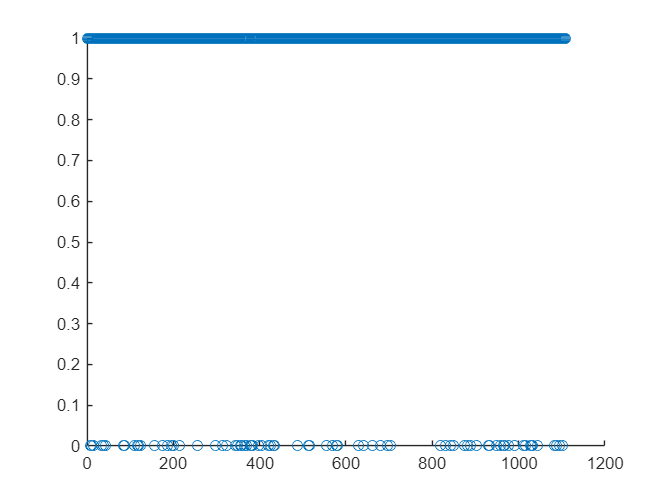

diff=res1-res2;
corrcet=[];
for i=1:length(diff)
    if diff(i)*(data_cut2{i,3}-1.5)<0
        corrcet(i)=1;
    else
        corrcet(i)=0;
    end
end
scatter(1:1:1109,corrcet)

c=sum(corrcet)/1109

c = 0.9306